datasetPath = "C:\UAlbany\2026\Spring 2026\ECE 465 - Machine Learning\speech_commands_v0.02";

ads = audioDatastore(datasetPath,'IncludeSubfolders', true, 'FileExtensions','.wav', 'LabelSource','foldernames');
countEachLabel(ads)

ans = 6×2 table
     Label     Count
    _______    _____

    go         3880 
    no         3941 
    silence     500 
    stop       3872 
    unknown    3100 
    yes        4044 


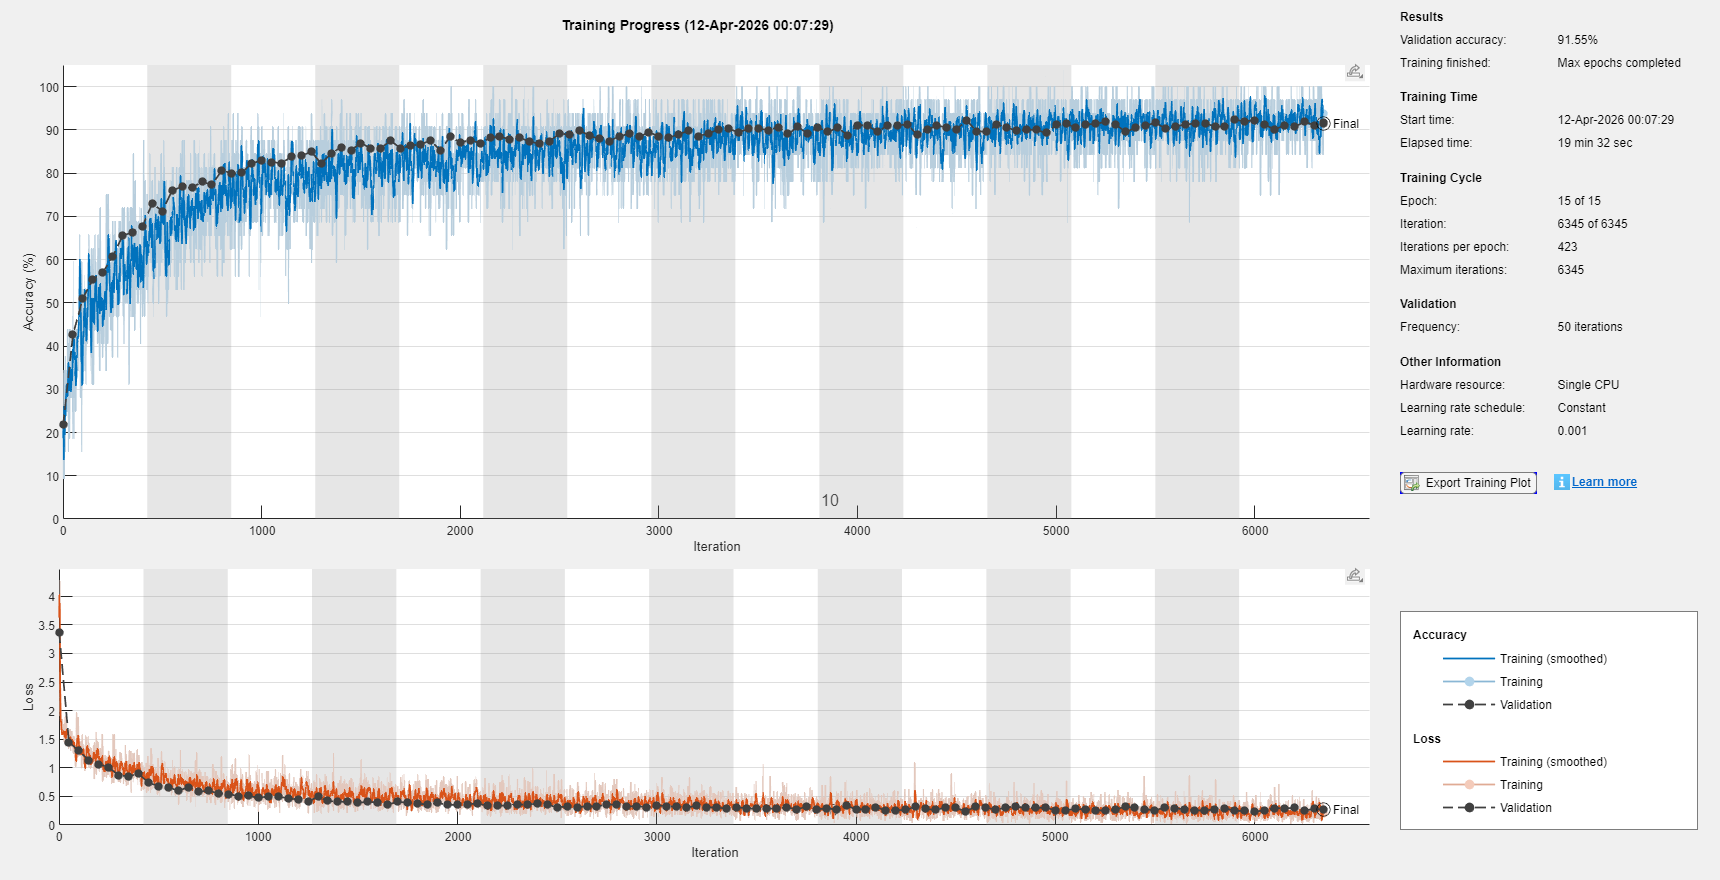


%Split into training testing and validation data
[adsTrain, adsTemp] = splitEachLabel(ads, 0.7);

[adsValidation, adsTest] = splitEachLabel(adsTemp, 0.5);

%get mel spectrograms for all training files
numTrainFiles = numel(adsTrain.Files);
XTrain = zeros(64,64,1,numTrainFiles);
YTrain = adsTrain.Labels;

%created silence category
%this is also used as noise when making our training data
silencePath = fullfile(datasetPath, "silence");
silenceADS = audioDatastore(silencePath,'IncludeSubfolders', true,'FileExtensions', '.wav');

for i = 1:numTrainFiles
    [audio, fs] = audioread(adsTrain.Files{i});

    if size(audio,2) > 1
        audio = mean(audio,2);
    end

    %makes every audio clip exactly 1 second long
    targetLength = fs;
    if length(audio) < targetLength
        audio = [audio; zeros(targetLength - length(audio), 1)];
    else
        audio = audio(1:targetLength);
    end
    
    %normalizes the audio so volume differences do not affect training as much
    audio = audio ./ (max(abs(audio)) + 1e-6);
    audioUsed = audio;

    label = string(adsTrain.Labels(i));

    % random time shift for all non-silence classes
    if label ~= "silence" && rand < 0.5
        shift = randi([-1600, 1600]);
        if shift > 0
            audioUsed = [zeros(shift,1); audioUsed(1:end-shift)];
        elseif shift < 0
            s = abs(shift);
            audioUsed = [audioUsed(s+1:end); zeros(s,1)];
        end
    end

    %add random gain
    if label ~= "silence" && rand < 0.5
        gain = 0.8 + 0.4*rand;
        audioUsed = gain * audioUsed;
    end

    % Add background noise only to non-silence samples, and only sometimes
    if label ~= "silence" && rand < 0.5

        silenceIndex = randi(numel(silenceADS.Files));
        [noiseChunk, noiseFs] = audioread(silenceADS.Files{silenceIndex});
        
        if noiseFs ~= fs
            noiseChunk = resample(noiseChunk, fs, noiseFs);
        end
        
        if size(noiseChunk,2) > 1
            noiseChunk = mean(noiseChunk,2);
        end

        if length(noiseChunk) < targetLength
            noiseChunk = [noiseChunk; zeros(targetLength - length(noiseChunk), 1)];
        else
            noiseChunk = noiseChunk(1:targetLength);
        end
        
        %adds the noise
        noiseScale = 0.02 + 0.08*rand;
        audioUsed = audioUsed + noiseScale * noiseChunk;

    end
    %renormalizes after augmentation so the final audio stays in a consistent range
    audioUsed = audioUsed ./ (max(abs(audioUsed)) + 1e-6);

    %create mel spec
    melSpec = melSpectrogram(audioUsed, fs, 'NumBands',64);
    melSpec = log10(melSpec + 1e-6);
    melSpec = imresize(melSpec, [64 64]);
    
    XTrain(:,:,1,i) = melSpec;
end

%similar for validation files
numValidationFiles = numel(adsValidation.Files);
XValidation = zeros(64,64,1,numValidationFiles);
YValidation = adsValidation.Labels;

for i = 1:numValidationFiles
    [audio, fs] = audioread(adsValidation.Files{i});
    if size(audio,2) > 1
        audio = mean(audio,2);
    end
    targetLength = fs;
    if length(audio) < targetLength
        audio = [audio; zeros(targetLength - length(audio), 1)];
    else
        audio = audio(1:targetLength);
    end
    audio = audio ./ (max(abs(audio)) + 1e-6);

    melSpec = melSpectrogram(audio, fs, 'NumBands', 64);
    melSpec = log10(melSpec + 1e-6);
    melSpec = imresize(melSpec, [64 64]);
    XValidation(:,:,1,i) = melSpec;
end

%do same for test files
numTestFiles = numel(adsTest.Files);
XTest = zeros(64,64,1,numTestFiles);
YTest = adsTest.Labels;

for i = 1:numTestFiles
    [audio, fs] = audioread(adsTest.Files{i});

    if size(audio,2) > 1
        audio = mean(audio,2);
    end

    targetLength = fs;
    if length(audio) < targetLength
        audio = [audio; zeros(targetLength - length(audio), 1)];
    else
        audio = audio(1:targetLength);
    end

    audio = audio ./ (max(abs(audio)) + 1e-6);

    melSpec = melSpectrogram(audio, fs, 'NumBands', 64);
    melSpec = log10(melSpec + 1e-6);
    melSpec = imresize(melSpec, [64 64]);

    XTest(:,:,1,i) = melSpec;
end

%
layers = [  
    %tells MATLAB each input is a 64×64 grayscale image
    imageInputLayer([64 64 1])  
  
    %first convolution layer uses 16 filters to detect simple spectrogram features
    convolution2dLayer(3,16,Padding="same")  
    batchNormalizationLayer  
    
    %adds nonlinearity so the network can learn more complex patterns
    reluLayer  
    
    %reduces the image size while keeping the strongest features
    maxPooling2dLayer(2,Stride=2)  
  
    %second convolution layer learns more detailed patterns using 32 filters
    convolution2dLayer(3,32,Padding="same")  
    batchNormalizationLayer  
    reluLayer  
    maxPooling2dLayer(2,Stride=2)  
  
    %third convolution layer learns higher-level features using 64 filters
    convolution2dLayer(3,64,Padding="same")  
    batchNormalizationLayer  
    reluLayer  
    maxPooling2dLayer(2,Stride=2)  
  
    %drops some neurons during training to help reduce overfitting
    dropoutLayer(0.4)  
  
    %fully connected layer combines extracted features into 64 learned outputs
    fullyConnectedLayer(64)  
    
    %adds nonlinearity before the final classification layer
    reluLayer  
    
    %another dropout layer helps prevent overfitting before classification
    dropoutLayer(0.3)  
  
    %maps the learned features to your command classes
    fullyConnectedLayer(numel(categories(YTrain)))  
    
    %turns outputs into class probabilities
    softmaxLayer  
    
    %computes the classification loss during training
    classificationLayer  
];

%Setting Training Options
options = trainingOptions("adam","MaxEpochs", 15,"MiniBatchSize", 32, ...
"ValidationData", {XValidation, YValidation},"Verbose", false, "Plots", "training-progress");

%save model when first ran then just load it once it's made so it doesnt
%keep training when not necessary

modelPath = "C:\UAlbany\2026\Spring 2026\ECE 465 - Machine Learning\speechCommandModelv5.mat";

if isfile(modelPath)
    load(modelPath)
else
    net = trainNetwork(XTrain,YTrain,layers,options);
    save(modelPath,"net")
end


%Test accuracy
YPred = classify(net, XTest);
accuracy = mean(YPred == YTest)

accuracy = 0.8659

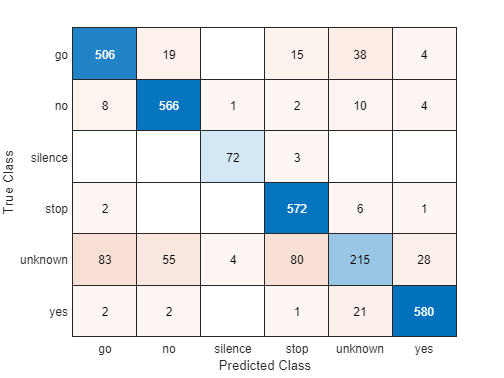


confusionchart(YTest,YPred)